## Annotating Plots

This code creates data for the interaction.

load datafile
data

data =     0.5300    0.5300    4.0753    0.5000
    1.7800    1.7800    6.6678    2.1328
    0.8600    0.8600    1.5177    3.6852
    1.6000    1.6000    3.6357    8.5389
    3.0000    3.0000    4.7243   10.1570
    6.1100    6.1100    9.0698    2.8739
    2.5400    2.5400    5.3002    4.4508


sample = data(:,1)

sample =     0.5300
    1.7800
    0.8600
    1.6000
    3.0000
    6.1100
    2.5400


density = data(:,2)

density =     0.5300
    1.7800
    0.8600
    1.6000
    3.0000
    6.1100
    2.5400


v1 = data(:,3)

v1 =     4.0753
    6.6678
    1.5177
    3.6357
    4.7243
    9.0698
    5.3002


v2 = data(:,4)

v2 =     0.5000
    2.1328
    3.6852
    8.5389
   10.1570
    2.8739
    4.4508


mass1 = density.*v1

mass1 =     2.1599
   11.8687
    1.3052
    5.8171
   14.1729
   55.4165
   13.4625


mass2 = density.*v2

mass2 =     0.2650
    3.7964
    3.1693
   13.6622
   30.4710
   17.5595
   11.3050


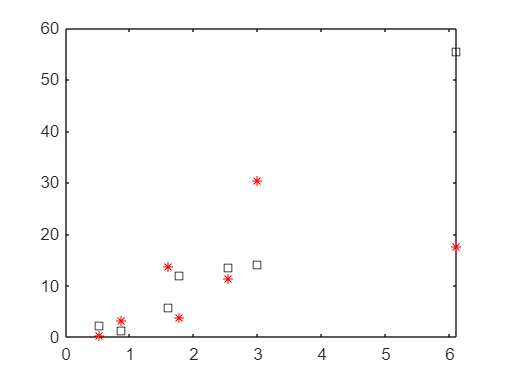


plot(sample,mass1,"ks")
hold on
plot(sample,mass2,"r*")
hold off

**Task 1**

You can add labels to plots using plot annotation functions, such as `title`.  The input to these functions is text. Text in MATLAB is enclosed in double quotes (`"`).

`title``(``"Plot Title"``)`

Task

Add the title `"Sample Mass"` to the existing plot.

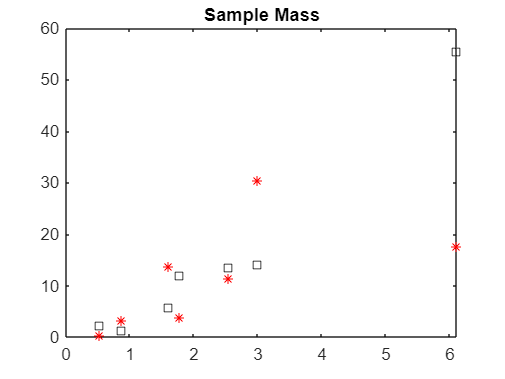

title("Sample Mass")

**Task 2**

Add the label `"Mass (g)"` by using the `ylabel` function.

ylabel("Mass (g)")

**Task 3**

You can add a legend to your plot using the `legend` function.

`legend``(``"a"``,``"b"``,``"c"``)`

**Task**

Create a legend with the labels `"Exp A"` and `"Exp B"`, in that order.

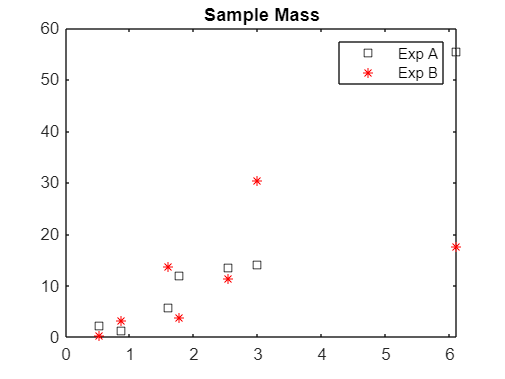

legend("Exp A", "Exp B")

**Further Practice**

You can use the value of a variable in plot annotations by joining text with the variable.

`bar``(``data``(``3``,:``))`

`title``(``"Sample "` `+` `sample``(``3``)` `+` `" Data"``)`

bar(data(3,:))
Sample3=sample(3)

Sample3 = 0.8600

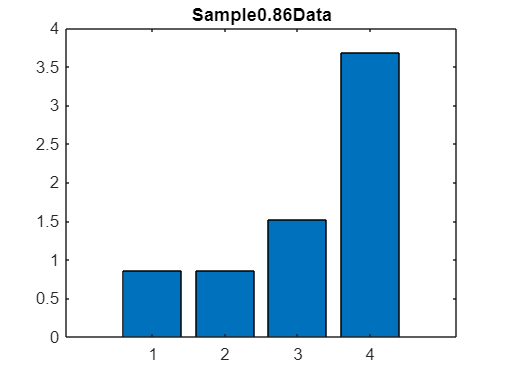

title("Sample"+sample(3)+"Data")